clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]


param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


simtime = 10*60;

% param.model.Dg*param.ctrl.Lambda_Bar

% Skriver en diagonal -1 på integralstaten.
% for i=1:4
%     param.model.A(3*i,3*i) = -1;
% end

## Control

% [param.ctrl.Ks] = control.DesignProcedure1(param,0); 
param.ctrl.Ks = control.DesignProcedure2(param,0,0);

Evaluation of design procedure 2 
Q is positive definite


ans =     0.0016    0.0016    0.0016    0.0150    0.2695    0.2715    0.2718    0.2750    2.7455    3.9375    4.0292    4.1667


Gamma is found to be:


ans = 1.0203

Eigenvalues of the decoupled systems are all negative 


ans =    -4.2846   -2.7730   -0.0498  -31.1007   -4.0327   -0.0204  -35.3673   -3.9953   -0.0204  -29.1618   -3.9953   -0.0195


Eigenvalues of the coupled systems are all negative 


ans =   -82.1771  -71.2049  -56.7517   -6.7556   -3.7411   -4.0336   -3.9960   -3.9961   -0.0497   -0.0195   -0.0204   -0.0204



%param.ctrl.Ks = control.DesignProcedureDScalingDiag(param,0);
%param.ctrl.Ks = control.DesignProcedureFunky(param,0);
%param.ctrl.Ks = control.DesignRobust(param,0);

K = blkdiag(param.ctrl.Ks(:,:,1),param.ctrl.Ks(:,:,2),param.ctrl.Ks(:,:,3),param.ctrl.Ks(:,:,4));

s = tf('s');
M = K * eye(12)/(s * eye(12) - (param.model.A + param.model.B * K * eye(12)) )*param.model.B;
hinfnorm(M)

ans = 1.0141

## Structured uncertainties

s = tf('s');

w = 1;
M = K*eye(12)/(s*eye(12) - ( param.model.A + param.model.B*K*eye(12) ) )*param.model.B;
hinfnorm(M)

ans = 1.0141

max(max(sigma(M)))

ans = 1.0141

W = logspace(-1,3,400);
SV = sigma(M, W)

SV =     1.0029    1.0029    1.0030    1.0030    1.0030    1.0031    1.0031    1.0032    1.0032    1.0032    1.0033    1.0033    1.0034    1.0034    1.0034    1.0035    1.0035    1.0036    1.0036    1.0037    1.0037    1.0038    1.0038    1.0039    1.0039    1.0040    1.0040    1.0041    1.0041    1.0042    1.0042    1.0043    1.0043    1.0044    1.0044    1.0045    1.0045    1.0046    1.0047    1.0047    1.0048    1.0049    1.0049    1.0050    1.0050    1.0051    1.0052    1.0053    1.0053    1.0054
    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    

spectral = zeros(1,length(W));
Ms = freqresp(M,W);
for i=1:length(W)   
    spectral(i) = abs(eigs(Ms(:,:,i),1));
end

[bounds,muinfo]  = mussv(frd(M,W),[4,0],'an');

Points completed: 400/400


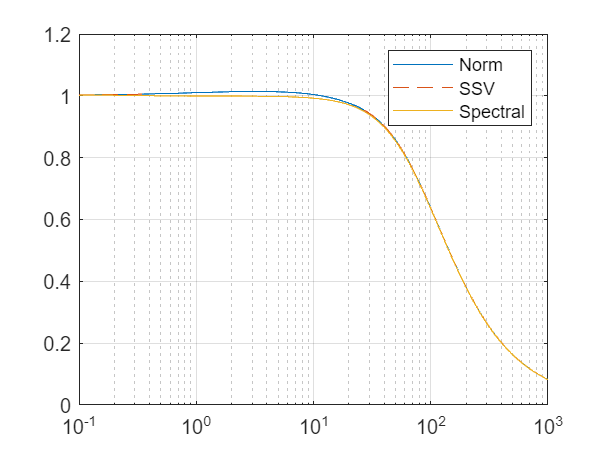


[VDelta,VSigma,VLmi] = mussvextract(muinfo);
VDelta.responsedata(:,:,:);
upperBound = bounds(1).ResponseData(:);

figure()
semilogx(W,max(SV),W,upperBound,'--',W,spectral)
% ylim([0;4])
legend('Norm', 'SSV', 'Spectral')
grid on

set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
% saveas(gcf,'../Images/SSV_PLOT_Procedure2','epsc')

% H = [An, B*B'; -(K*eye(12))'*(K*eye(12)), -An']

% W = logspace(-1,3,100);
% Ms = freqresp(Mn2,W);
% yalmip('clear')
% gamma = 0.01;
% % D = sdpvar(4,4,'symmetric','complex');
% % Q = D*D'
% D = sdpvar(4,4,'toeplitz','complex');
% Q = D-diag(imag(diag(D)))*sqrt(-1)
% constraints = [Ms(40)*Q*Ms(40)' <= gamma^2*Q, Q>=0]
% options = sdpsettings('verbose',0,'solver','mosek');
% sol = optimize(constraints,[],options)
% value(Q)
% eig(value(Q))


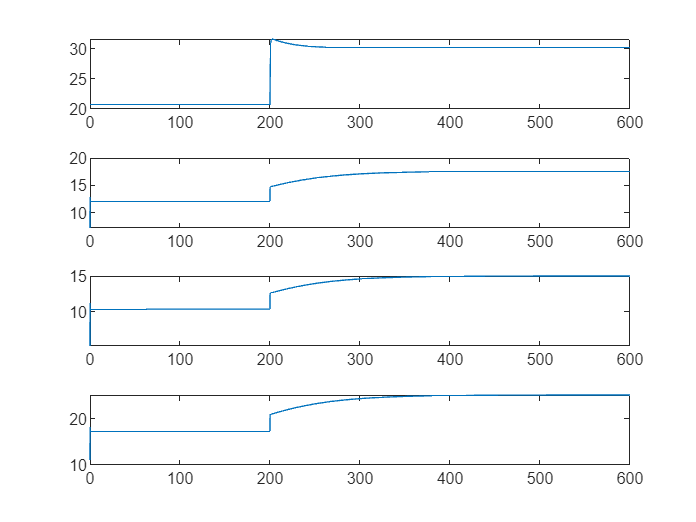

figure()
tiledlayout('vertical')
for i=1:4
    x0 = [param.ctrl.T_wOP(i); param.ctrl.T_aOP(i); 0];
    [t,x] = ode23s(@(t,x)model.decoupledDynamics(t,x,i,param,200),[0 simtime],x0);
    decoupledResults(i).time = t;
    decoupledResults(i).Tw = x(:,1);
    decoupledResults(i).Ta = x(:,2);
    decoupledResults(i).T = x(:,3);

    q = zeros(1,length(t));
      for k=1:length(t)
        [~,q(k)] = model.decoupledDynamics(t(k),x(k,:)',i,param);
      end
      nexttile
      plot(t,q*3600)
end

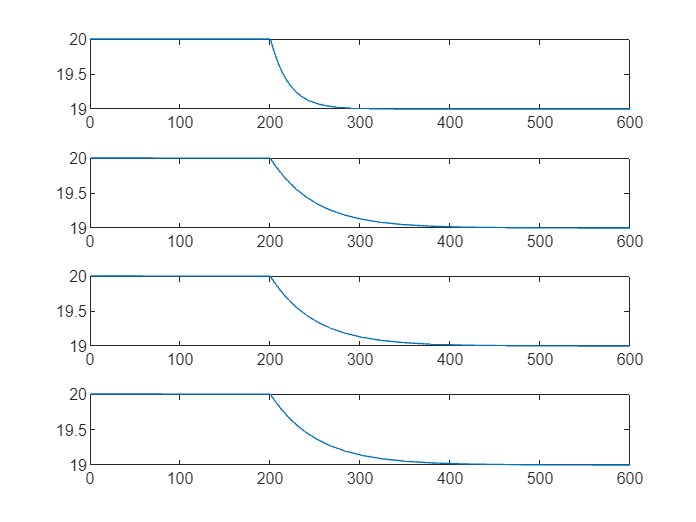



figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15)
end

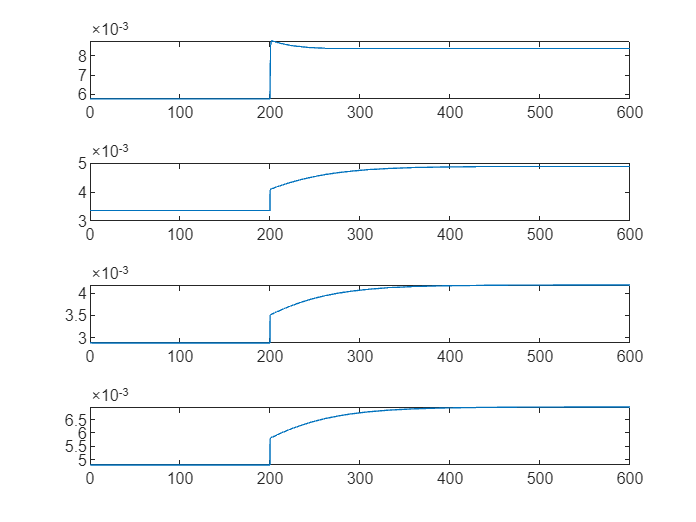

x0 = [param.ctrl.T_wOP.'; param.ctrl.T_aOP.'; zeros(4,1)];
% options = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode23s(@(t,x)model.coupledDynamics(t,x,param,200),[0 simtime],x0);
coupledResults.time = t;
coupledResults.Tw = x(:,1:4);
coupledResults.Ta = x(:,5:8);
coupledResults.T = x(:,9:12);

q = zeros(4,length(x(:,1)));
for k=1:length(x(:,1))
  [~,q(:,k)] = model.coupledDynamics(t(k),x(k,:)',param);
end
figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(t,q(i,:));
end

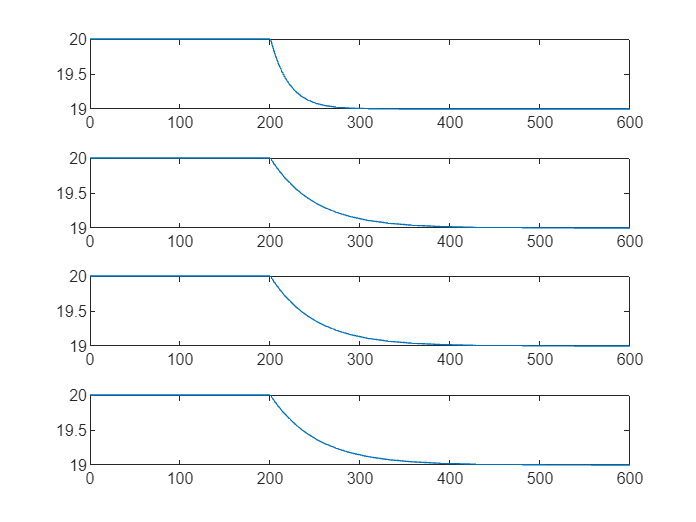



figure()
tiledlayout('vertical')

for i=1:4
    nexttile
    plot(coupledResults.time,coupledResults.Ta(:,i)-273.15)
end

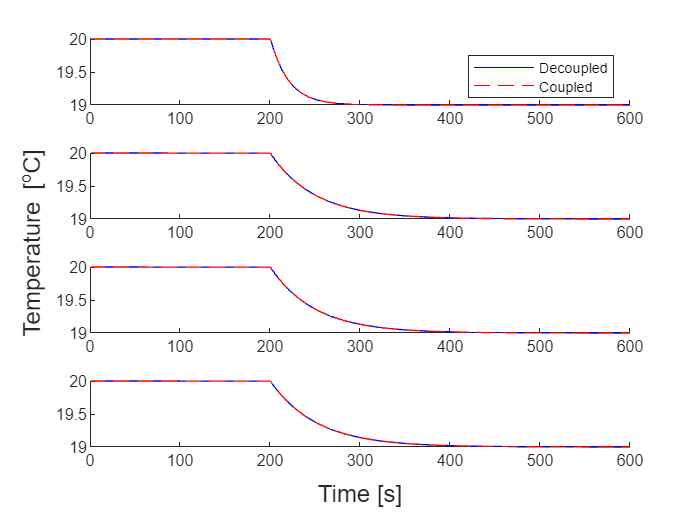

figure()
f = tiledlayout('vertical');
for i=1:4
    nexttile
    hold on
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15,'blue')
    plot(coupledResults.time,coupledResults.Ta(:,i)-273.15,['red','--'])
    if i==1
        legend('Decoupled','Coupled',Location='northeast')
    end
    hold off
end
xlabel(f,'Time [s]')
ylabel(f,'Temperature [^{o}C]')